# Probing the Limits of Latent Reconstruction Methods

## 1. Ground Truth & Forward Model

**Why? **

              Building intuition for what the problem is. 

**Tasks:**

- Plot true latent trajectories , color‑coded by time. Compute their power spectra. 

- Plot example EEG trajectories  and compute their power spectra.

- Provide a short rationale (2‑3 sentences each):

- Which features of  are likely preserved in ?

- Which features (especially high-frequency) are likely lost or distorted?

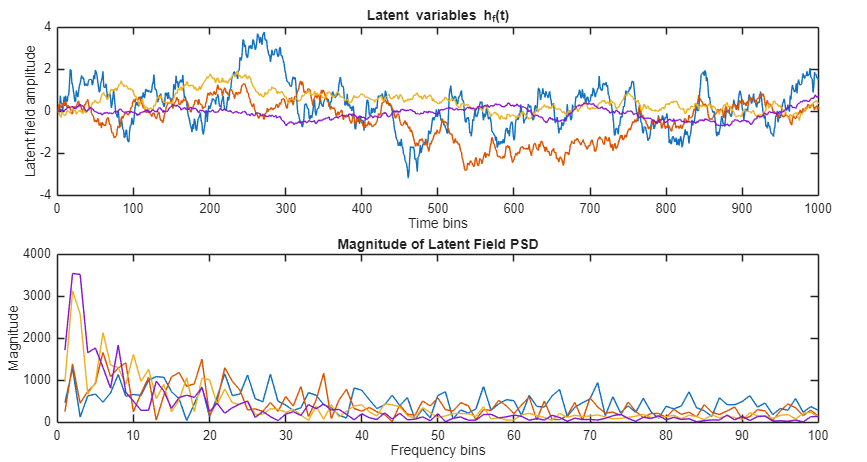

clear;clc;

% Parameter setup and model invocation

param.N_neur = 256; % Number of "neurons" (binary units)
param.N_F = 4; % Number of latent fields hₘ(t)
param.tau_F = [0.3 1 3 10]; % Time constants (in seconds) for each OU field
%ones(1, param.N_F); % controls the time constants of the latents
param.T = 100; % Total simulation time (in seconds)

param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
param.eta_val = 3;
param.eps_val = 1*param.eta_val; % 2.67 previous, "Inverse temperature" and silence bias
[s_i, param, h_f] = sampleMorrellModel(param);

h_f_psd = fft(h_f);
h_f_psd_mag = abs(h_f_psd); % Compute the magnitude of the FFT
figure('Position',[50 50 1500 800])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
plot(h_f)
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);

nexttile
plot(h_f_psd_mag)
xlabel('Frequency bins')
ylabel('Magnitude')
title('Magnitude of Latent Field PSD')
xlim([0 100]);

target_bin_size = 0.05; % 50 ms
tau = 25; % Post-synaptic kernel, Alpha kernel's number of bins to the peak of the kernel
smooth_sigma = 5; % Std. Dev. of the Gaussian kernel in bins
group_size = 8; % grouping of neurons per channel

[s_eeg_like, h_f_processed] = spike_to_eeg(s_i, h_f, param, target_bin_size, tau, group_size, smooth_sigma);

% 2. Manually build a minimal EEG structure
EEG = eeg_emptyset();
EEG.data   = s_eeg_like;
EEG.nbchan = size(EEG.data, 1);   % number of "channels" = neurons
EEG.pnts   = size(EEG.data, 2);   % number of time points
EEG.trials = 1;                   % continuous data
EEG.srate  = 100;                 % arbitrary sample rate (adjust if needed)
EEG.xmin   = 0;
EEG = eeg_checkset(EEG);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Plotting data using axis size [0.110714,0.116429]
limits: [xmin,xmax,ymin,ymax] = [ 0.0 19990.0 -3.21 3.21]
Plotting 1 traces of 2000 frames with colors: 'b' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32
pop_plotdata(EEG, 1, [1:32] , [1:1], '', 0, 1, [0 0]);


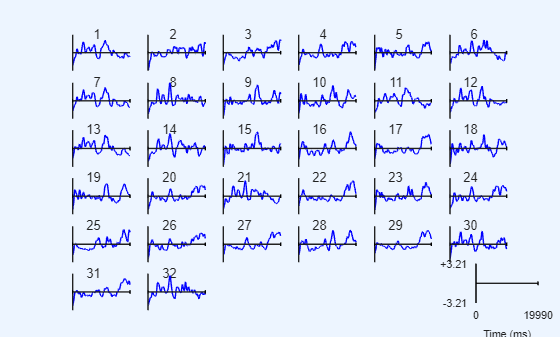

pop_plotdata(EEG,1, 1:32);

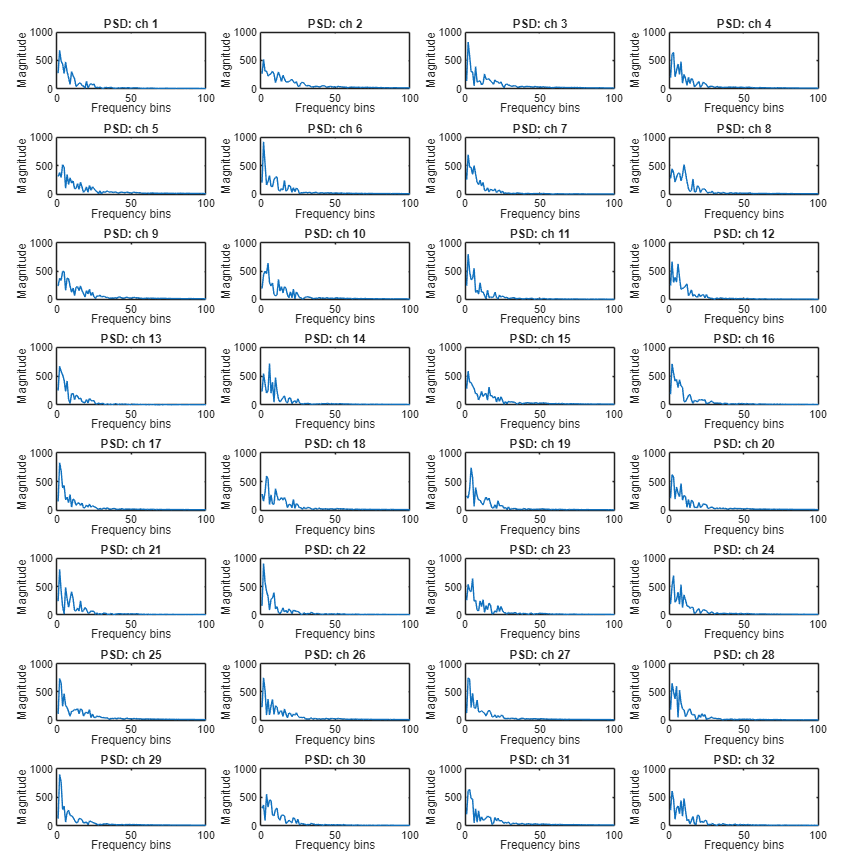

s_eeg_like_T = s_eeg_like';
eeg_psd = fft(s_eeg_like_T);
eeg_psd_mag = abs(eeg_psd); % Compute the magnitude of the FFT

%[psd, f_psd] = pwelch(s_eeg_like_T,param.T);

figure('Position',[50 50 2000 2000])
tiledlayout(8, 4, 'TileSpacing', 'compact', 'Padding', 'compact');

% nexttile
% plot(f_psd, log10(psd)) % log10(f_psd)
% xlabel('Frequency (Hz)') % log_{10} 
% ylabel('log_{10} Power spectral density')
% title('Log power spectrum of local readout')
for ch = 1:32
    nexttile
    plot(eeg_psd_mag(:, ch));
    xlabel('Frequency bins')
    ylabel('Magnitude')
    title(['PSD: ch ', num2str(ch)] )
    xlim([0 100]);
    ylim([0 1000]);
end

- 0- ~50 Hz frequecy components of Z (t) are reflexted in X(t).

## 2. Dimensionality Reduction Methods

**Why? **

              Examine *overall*accuracy metrics and check against visualization of reconstructed trajectories. 

**Select at least:**

- Two **linear methods** (e.g., PCA or ICA)

- Two **nonlinear methods** (e.g., UMAP, neural network, t-SNE)

**Tasks for each method:**

- Reconstruct from .

- Report:

- Total   between   and  

- Visual comparison of trajectories

## 3. Frequency‑Resolved Analysis

**Why? **

              The latent variables may have different frequency content than the EEG signal. We want to know the limits of reconstruction and signatures of failure. A. CPSD / Spectral R2(f)R^2(f)

- Compute Fourier transforms .

- For each dimension:

- Plot  across frequencies (for each latent dimension). Recommended to divide long time series into shorter “trials” (~3 seconds each) and average over these. 

B. Multitaper Coherence

- Estimate coherence using multitaper methods (include 95% confidence intervals). Use Chronux (http://chronux.org)

- Identify frequency bands where coherence drops below statistical significance.

- Compare these bands across different reconstruction methods.